## PART 1: KINEMATICS

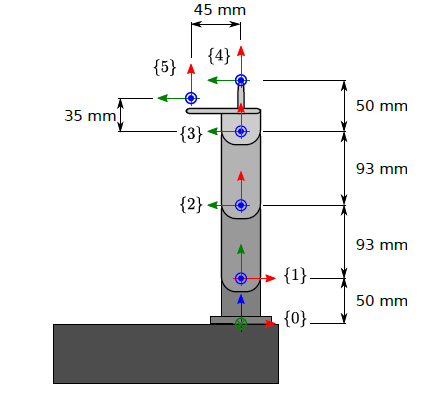

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;
% % Uncomment for symbolic representation
syms t1 t2 t3 t4 

% {0} -> {1}
T01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) L01;
       0 0 0 1];
% {1} -> {2}
T12 = [cos(t2) -sin(t2) 0 L12;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];
% {2} -> {3}
T23 = [1 0 0 L23;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {4}
T34 = [1 0 0 L34;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {5}
T35 = [1 0 0 L35;
       0 1 0 L45;
       0 0 1 0;
       0 0 0 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & 0 & 143\,\cos\left(t_{2}\right)+93\\ \cos\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{1}\right)\,\cos\left(t_{2}\right) & -\sin\left(t_{1}\right) & 143\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\\ \sin\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{2}\right)\,\sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 143\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & 0 & 128\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)+93\\ \cos\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{1}\right)\,\cos\left(t_{2}\right) & -\sin\left(t_{1}\right) & 45\,\cos\left(t_{1}\right)\,\cos\left(t_{2}\right)+128\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\\ \sin\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{2}\right)\,\sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 45\,\cos\left(t_{2}\right)\,\sin\left(t_{1}\right)+128\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

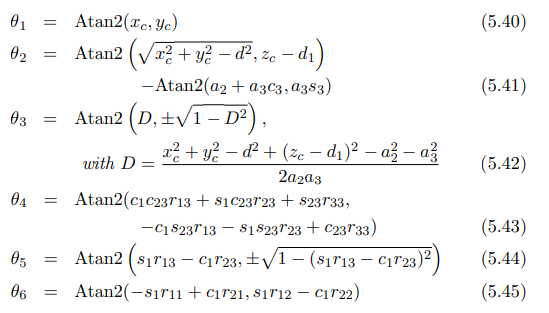

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(t2) -sin(t2) 0 0;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



t1 = atan2(xc,yc);

t3 = atan2(D, sqrt(1-D^2));

t2 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(t3), L23*sin(t3));

R01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(t2) -sin(t2) 0 0;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;


t4 =atan2(cos(t1)*cos(t2+t3)*R(1,3) + sin(t1)*cos(t2+t3)*R(2,3) + sin(t2+t3)*R(3,3), -cos(t1)*sin(t2+t3)*R(1,3) - sin(t1)*sin(t2+t3)*R(2,3)+cos(t2+t3)*R(3,3));

% I think the following is irrelevant




% % {0} -> {1}
% T01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) L01;
%        0 0 0 1];
% % {1} -> {2}
% T12 = [cos(t2) -sin(t2) 0 L12;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% % {2} -> {3}
% T23 = [1 0 0 L23;
%        0 1 0 0;
%        0 0 1 0;
%        0 0 0 1];
% % {3} -> {4}
% T34 = [1 0 0 L34;
%        0 1 0 0;
%        0 0 1 0;
%        0 0 0 1];
% % {3} -> {5}
% T35 = [1 0 0 L35;
%        0 1 0 L45;
%        0 0 1 0;
%        0 0 0 1];
% 
% % Transformation from {0} to {4}
% T04_Re = T01*T12*T23*T34

T04_Re =     0.4248   -0.9053         0  153.7527
    0.6401    0.3004   -0.7071   91.5372
    0.6401    0.3004    0.7071  141.5372
         0         0         0    1.0000


% 
% % Transformation from {0} to {5}
% T05_Re = T01*T12*T23*T35

T05_Re =     0.4248   -0.9053         0  106.6430
    0.6401    0.3004   -0.7071   95.4538
    0.6401    0.3004    0.7071  145.4538
         0         0         0    1.0000


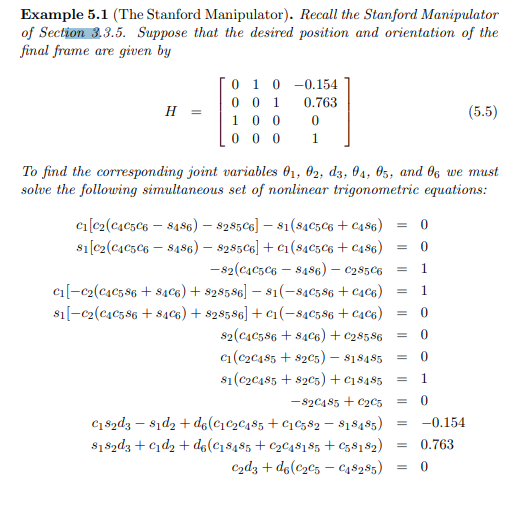

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.


% %H11 = solve(T04(1,1)==T04_Re(1,1)) % gives an approximate value for t2 that then needs to be inserted back into the cosine
% H = ones(4)
% H11 = double(subs(T04(1,1),solve(T04(1,1)==T04_Re(1,1))));
% H11 = H11(1)
% H11 = double(subs(T04(1,1),solve(T04(1,1)==T04_Re(1,1))));
% H12 = double(subs(T04(1,2),solve(T04(1,2)==T04_Re(1,2))));
% %H13 = double(subs(T04(1,3),solve(T04(1,3)==T04_Re(1,3)))) % value is 0
% 
% H14 = double(subs(T04(1,4),solve(T04(1,4)==T04_Re(1,4))));
% H21 = double(subs(T04(2,1),solve(T04(2,1)==T04_Re(2,1))));
% H22 = double(subs(T04(2,2),solve(T04(2,2)==T04_Re(2,2))));
% H23 = double(subs(T04(2,3),solve(T04(2,3)==T04_Re(2,3))));
% H24 = double(subs(T04(2,4),solve(T04(2,4)==T04_Re(2,4))));
% H31 = double(subs(T04(3,1),solve(T04(3,1)==T04_Re(3,1))));
% H32 = double(subs(T04(3,2),solve(T04(3,2)==T04_Re(3,2))));
% H33 = double(subs(T04(3,3),solve(T04(3,3)==T04_Re(3,3))));
% H34 = double(subs(T04(3,4),solve(T04(3,4)==T04_Re(3,4))));
% %H41 = double(subs(T04(4,1),solve(T04(4,1)==T04_Re(4,1))))
% %H42 = double(subs(T04(4,2),solve(T04(4,2)==T04_Re(4,2))))
% %H43 = double(subs(T04(4,3),solve(T04(4,3)==T04_Re(4,3))))
% %H44 = double(subs(T04(4,4),solve(T04(4,4)==T04_Re(4,4))))
% 
% H(1,1) = H11(1);
% H(1,2) = H12(1);
% H(1,3) = 0;
% H(1,4) = H14(1);
% H(2,1) = H21(1);
% H(2,2) = H22(1);
% H(2,3) = H23(1);
% H(2,4) = H24(1);
% H(3,1) = H31(1);
% H(3,2) = H32(1);
% H(3,3) = H33(1);
% H(3,4) = H34(1);
% H(4,1) = 0;
% H(4,2) = 0;
% H(4,3) = 0;
% H(4,4) = 1;
% 
% 
% H



## **Problem 3:**

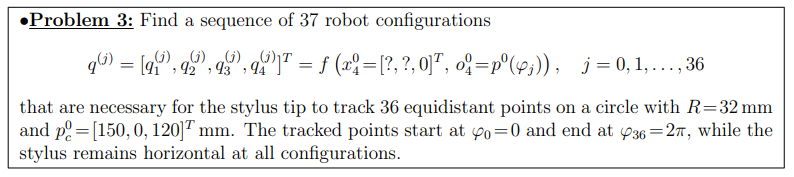


% origin of the circle to be traced
xc = 150;
yc = 100;
zc = 120;

angles = 0:2*pi/36:2*pi % this is the phi angle reported in the previous line

angles =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708    1.7453    1.9199    2.0944    2.2689    2.4435    2.6180    2.7925    2.9671    3.1416    3.3161    3.4907    3.6652    3.8397    4.0143    4.1888    4.3633    4.5379    4.7124    4.8869    5.0615    5.2360    5.4105    5.5851    5.7596    5.9341    6.1087    6.2832


dy = cos(angles)*16;
dz = sin(angles)*16;

x = zeros(1,length(angles))

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = yc + dy

y =   116.0000  115.7569  115.0351  113.8564  112.2567  110.2846  108.0000  105.4723  102.7784  100.0000   97.2216   94.5277   92.0000   89.7154   87.7433   86.1436   84.9649   84.2431   84.0000   84.2431   84.9649   86.1436   87.7433   89.7154   92.0000   94.5277   97.2216  100.0000  102.7784  105.4723  108.0000  110.2846  112.2567  113.8564  115.0351  115.7569  116.0000


z = zc + dz

z =   120.0000  122.7784  125.4723  128.0000  130.2846  132.2567  133.8564  135.0351  135.7569  136.0000  135.7569  135.0351  133.8564  132.2567  130.2846  128.0000  125.4723  122.7784  120.0000  117.2216  114.5277  112.0000  109.7154  107.7433  106.1436  104.9649  104.2431  104.0000  104.2431  104.9649  106.1436  107.7433  109.7154  112.0000  114.5277  117.2216  120.0000



[t1,t2,t3] = theta(x,y,z)

t1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


t2 =    -0.8166   -0.8250   -0.8385   -0.8566   -0.8792   -0.9057   -0.9357   -0.9686   -1.0037   -1.0404   -1.0778   -1.1150   -1.1509   -1.1845   -1.2145   -1.2397   -1.2590   -1.2710   -1.2747   -1.2693   -1.2546   -1.2307   -1.1985   -1.1599   -1.1168   -1.0717   -1.0269   -0.9841   -0.9448   -0.9098   -0.8799   -0.8555   -0.8365   -0.8232   -0.8156   -0.8134   -0.8166


t3 =    -0.4543   -0.4325   -0.4177   -0.4103   -0.4103   -0.4178   -0.4326   -0.4543   -0.4827   -0.5171   -0.5567   -0.6009   -0.6487   -0.6991   -0.7509   -0.8028   -0.8532   -0.9003   -0.9421   -0.9764   -1.0009   -1.0137   -1.0137   -1.0009   -0.9764   -0.9421   -0.9002   -0.8531   -0.8027   -0.7508   -0.6990   -0.6487   -0.6009   -0.5567   -0.5170   -0.4827   -0.4543



%t1 = theta1(x,y);
%t3 = theta3(x,y,z);
%t2 = theta2(x,y,z,t3);
t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

t4 =     4.4125    4.3992    4.3978    4.4085    4.4310    4.4650    4.5098    4.5645    4.6280    4.6991    4.7762    4.8575    4.9412    5.0252    5.1070    5.1841    5.2537    5.3129    5.3584    5.3873    5.3971    5.3859    5.3538    5.3023    5.2348    5.1554    5.0687    4.9788    4.8890    4.8022    4.7206    4.6457    4.5790    4.5215    4.4742    4.4376    4.4125



% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));



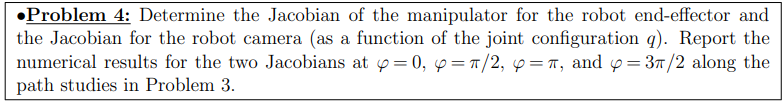

% if you need help figuring out the angles contact me
